Extract pre-recorded data. IMPORTANT: change path name to the path of test data on your computer

path = "~/AirBeats/MATLAB files/timed_readings.txt";
mpudata = readtable(path);
mpudata.Properties.VariableNames = ["Time", "GyroX", "GyroY", "GyroZ", "AccelX", "AccelY", "AccelZ"]

mpudata = 391×7 table
    Time    GyroX    GyroY    GyroZ    AccelX    AccelY    AccelZ
    ____    _____    _____    _____    ______    ______    ______

    0.01    -0.28    -0.08    0.23      0.09         0      0.88 
    0.21    -0.31     0.01    0.21      0.09         0      0.89 
    0.42    -0.28    -0.16    0.24      0.09         0      0.89 
    0.62     -0.3     0.25    0.22      0.09      0.01      0.89 
    0.83    -0.27    -0.27    0.23      0.09      0.01      0.88 
    1.03    -0.28     0.14    0.22      0.09         0      0.88 
    1.24    -0.29     0.02    0.23      0.09         0      0.89 
    1.44     -0.3    -0.11    0.21      0.09      0.01      0.88 
    1.65    -0.31     0.19    0.24      0.09         0      0.88 
    1.86    -

load mpu9250new.mat

Lets see how the GyroX data looks

plot(mpudata.Time, mpudata.GyroX, "b")
p = polyfit(mpudata.Time(1:100, 1), mpudata.GyroX(1:100, 1), 1);
hold on
OrientX = zeros(391,1);
% If you can improve this code please do
for c = 2:391
    OrientX(c) = OrientX(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(mpudata.GyroX(c-1));
end
plot(mpudata.Time, OrientX(1:391), "r")
xlabel("Time [s]")
ylabel("Degrees")
legend("readingX", "orientationX")
hold off

Not much insight (rather than the curve slanting downwards), but lets look at the first 20 seconds or so when the sensor is supposed to be stationary

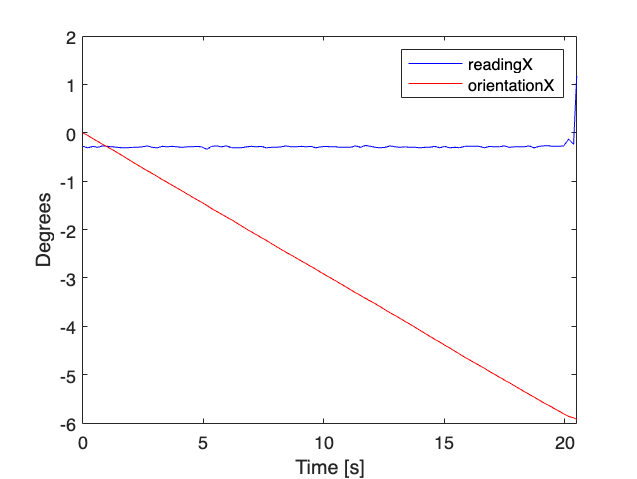

xlim([0 20.5])

This is when the sensor drift (or bias) becomes apparent. Even in a stationary setting, the sensor seems to indicate that there is some rotation in the x-direction. Let us look at the other axes as well.

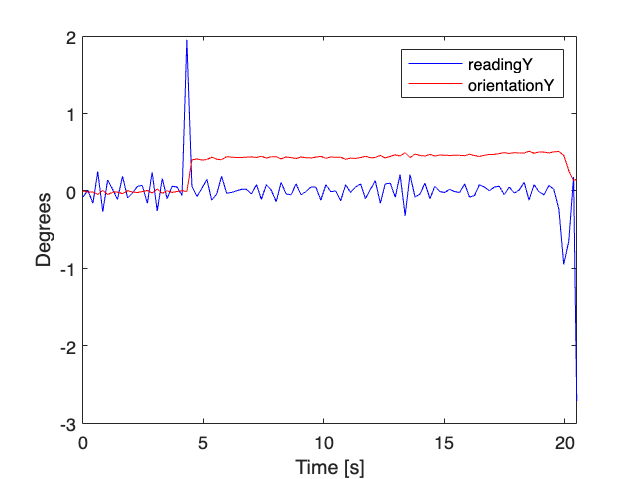

OrientY = zeros(391,1); OrientZ = zeros(391,1);
for c = 2:391
    OrientY(c) = OrientY(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(mpudata.GyroY(c-1));
    OrientZ(c) = OrientZ(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(mpudata.GyroZ(c-1));
end

plot(mpudata.Time, mpudata.GyroY, "b")
hold on
plot(mpudata.Time, OrientY, "r")
legend("readingY", "orientationY")
xlim([0 20.5])
xlabel("Time [s]")
ylabel("Degrees")
hold off

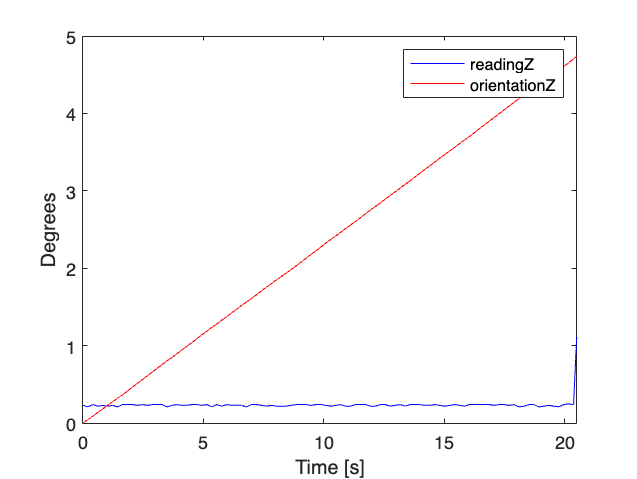


plot(mpudata.Time, mpudata.GyroZ, "b")
hold on
plot(mpudata.Time, OrientZ, "r")
legend("readingZ", "orientationZ")
xlim([0 20.5])
xlabel("Time [s]")
ylabel("Degrees")
hold off

From this we can see that GyroX has a negative bias, GyroY has a neutral (?) bias, and GyroZ has a positive bias. How do we fix thisssssss?

One thing we can try is reject all readings in the range of the bias.

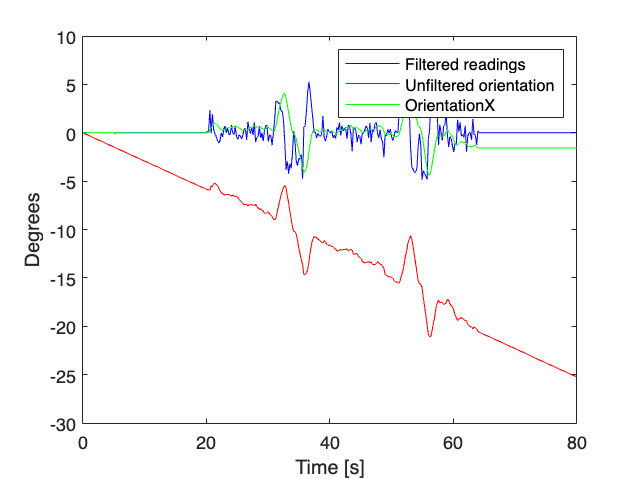

GyroX = mpudata.GyroX + 0.30; GyroY = mpudata.GyroY + 0.1; GyroZ = mpudata.GyroZ - 0.225;

% Reject all readings in drift range
GyroX((GyroX >= -0.04) & (GyroX <= 0.04)) = 0;
GyroY((GyroY >= -0.3) & (GyroY <= 0.3)) = 0;
GyroZ((GyroZ >= -0.025) & (GyroZ <= 0.025)) = 0;

% Calculate orientation with filtered values now
filterX = zeros(391, 1); filterY = zeros(391, 1); filterZ = zeros(391,1);
for c = 2:391
    filterX(c) = filterX(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(GyroX(c-1)+GyroX(c))/2;
    filterY(c) = filterY(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(GyroY(c-1)+GyroY(c))/2;
    filterZ(c) = filterZ(c-1) + (mpudata.Time(c) - mpudata.Time(c-1))*(GyroZ(c-1)+GyroZ(c))/2;
end

% Plot X-axis data
plot(mpudata.Time, GyroX, "b")
hold on
plot(mpudata.Time, OrientX, "r")
plot(mpudata.Time, filterX, "g")
legend("Filtered readings", "Unfiltered orientation", "OrientationX")
xlabel("Time [s]")
ylabel("Degrees")
xlim([0 80])
hold off

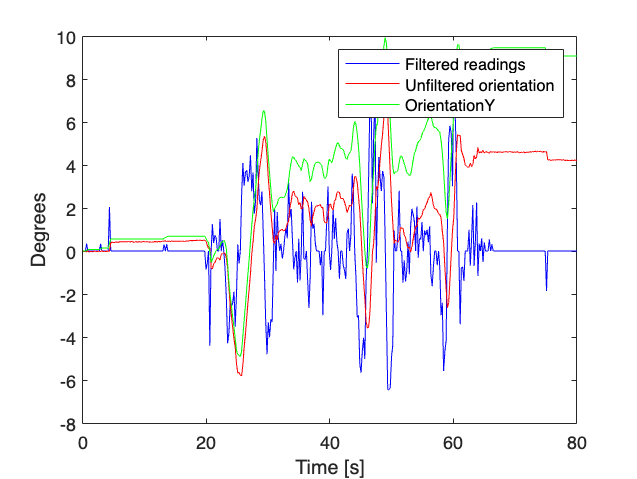


% Plot Y-axis data
plot(mpudata.Time, GyroY, "b")
hold on
plot(mpudata.Time, OrientY, "r")
plot(mpudata.Time, filterY, "g")
legend("Filtered readings", "Unfiltered orientation", "OrientationY")
xlabel("Time [s]")
ylabel("Degrees")
xlim([0 80])
hold off

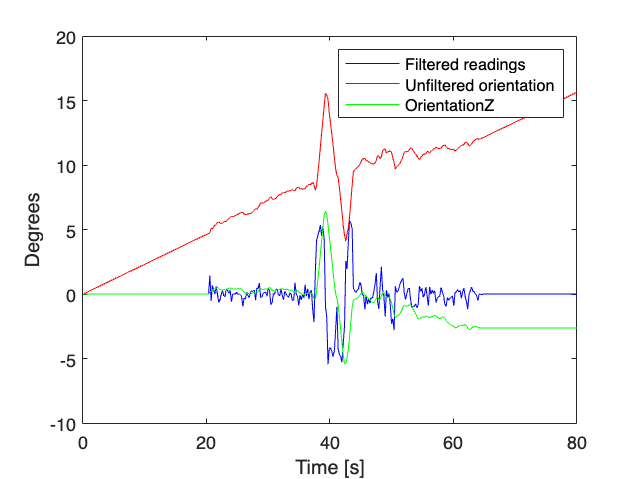


% Plot Z-axis data
plot(mpudata.Time, GyroZ, "b")
hold on
plot(mpudata.Time, OrientZ, "r")
plot(mpudata.Time, filterZ, "g")
legend("Filtered readings", "Unfiltered orientation", "OrientationZ")
xlabel("Time [s]")
ylabel("Degrees")
xlim([0 80])
hold off

Well that looks like an improvement (y axis wildin). However this is very jugadoo and we haven't really tested it out with a model yet. Our first task should be to implement a 3D model for atleast the orientation.

Let us save some variables and start work on the model.

save orient_dat.mat OrientX OrientY OrientZ filterX filterY filterZ

Now we will design a basic kalman filter for the purpose of denoising the sensor data

t = mpudata.Time

t =     0.0100
    0.2100
    0.4200
    0.6200
    0.8300
    1.0300
    1.2400
    1.4400
    1.6500
    1.8600


l = length(t);
gx = [t, mpudata.GyroX];
gy = [t, mpudata.GyroY];
gz = [t, mpudata.GyroZ];
ax = [t, mpudata.AccelX];
ay = [t, mpudata.AccelY];
az = [t, mpudata.AccelZ];
save sensor_data.mat t gx gy gz ax ay az

First we will manually remove the bias.

% removing the average value of all measurements during their stationary period
a = find((t<20)==0);
tl = a(1);

% These are the bias values
gx_ = mean(gx(1:tl, 2))

gx_ = -0.2892

gy_ = mean(gy(1:tl, 2))

gy_ = 0.0056

gz_ = mean(gz(1:tl, 2))

gz_ = 0.2311

ax_ = mean(ax(1:tl, 2))

ax_ = 0.0903

ay_ = mean(ay(1:tl, 2))

ay_ = 0.0051

az_ = mean(az(1:tl, 2))

az_ = 0.8856

gx = [gx(:,1), gx(:, 2) - gx_]

gx =     0.0100    0.0092
    0.2100   -0.0208
    0.4200    0.0092
    0.6200   -0.0108
    0.8300    0.0192
    1.0300    0.0092
    1.2400   -0.0008
    1.4400   -0.0108
    1.6500   -0.0208
    1.8600   -0.0208


gy = [gx(:,1), gy(:, 2) - gy_];
gz = [gx(:,1), gz(:, 2) - gz_];
ax = [ax(:,1), ax(:, 2) - ax_];
ay = [ay(:,1), ay(:, 2) - ay_];
az = [az(:,1), az(:, 2) - az_];

alphax = zeros(l,1);
alphay = zeros(l,1);
alphaz = zeros(l,1);
daxdt = zeros(l,1);
daydt = zeros(l,1);
dazdt = zeros(l,1);

for i = 2:l
    alphax(i) = (gx(i,2) - gx(i-1,2))/(t(i) - t(i-1));
    alphay(i) = (gy(i,2) - gy(i-1,2))/(t(i) - t(i-1));
    alphaz(i) = (gz(i,2) - gz(i-1,2))/(t(i) - t(i-1));
    daxdt(i) = (ax(i,2) - ax(i-1,2))/(t(i) - t(i-1));
    daydt(i) = (ay(i,2) - ay(i-1,2))/(t(i) - t(i-1));
    dazdt(i) = (az(i,2) - az(i-1,2))/(t(i) - t(i-1));
end

state = [t,gx(:,2),gy(:,2),gz(:,2),ax(:,2),ay(:,2),az(:,2)]

state =     0.0100    0.0092   -0.0856   -0.0011   -0.0003   -0.0051   -0.0056
    0.2100   -0.0208    0.0044   -0.0211   -0.0003   -0.0051    0.0044
    0.4200    0.0092   -0.1656    0.0089   -0.0003   -0.0051    0.0044
    0.6200   -0.0108    0.2444   -0.0111   -0.0003    0.0049    0.0044
    0.8300    0.0192   -0.2756   -0.0011   -0.0003    0.0049   -0.0056
    1.0300    0.0092    0.1344   -0.0111   -0.0003   -0.0051   -0.0056
    1.2400   -0.0008    0.0144   -0.0011   -0.0003   -0.0051    0.0044
    1.4400   -0.0108   -0.1156   -0.0211   -0.0003    0.0049   -0.0056
    1.6500   -0.0208    0.1844    0.0089   -0.0003   -0.0051   -0.0056
    1.8600   -0.0208   -0.0956    0.0089   -0.0003   -0.0051    0.0144


control = [t,alphax,alphay,alphaz,daxdt,daydt,dazdt]

control =     0.0100         0         0         0         0         0         0
    0.2100   -0.1500    0.4500   -0.1000         0         0    0.0500
    0.4200    0.1429   -0.8095    0.1429         0         0         0
    0.6200   -0.1000    2.0500   -0.1000         0    0.0500         0
    0.8300    0.1429   -2.4762    0.0476         0         0   -0.0476
    1.0300   -0.0500    2.0500   -0.0500         0   -0.0500         0
    1.2400   -0.0476   -0.5714    0.0476         0         0    0.0476
    1.4400   -0.0500   -0.6500   -0.1000         0    0.0500   -0.0500
    1.6500   -0.0476    1.4286    0.1429         0   -0.0476         0
    1.8600         0   -1.3333         0         0         0    0.0952


A = diag([1 1 1 1 1 1]);
B = diag([0.2 0.2 0.2 0.2 0.2 0.2]);
C = diag([1 1 1 1 1 1]);
D = 0

D = 0

fgx = out.filter.Data(:,1)

fgx =     0.0024
   -0.0013
   -0.0218
   -0.0010
   -0.0093
    0.0120
    0.0063
   -0.0045
   -0.0153
   -0.0240


fgy = out.filter.Data(:,2)

fgy =    -0.0199
   -0.0190
    0.0189
   -0.0479
    0.1932
   -0.1185
    0.1296
    0.0700
   -0.0194
    0.1270


fgz = out.filter.Data(:,3)

fgz =    -0.0000
   -0.0037
   -0.0163
    0.0039
   -0.0093
   -0.0052
   -0.0103
   -0.0072
   -0.0162
    0.0026


fax = out.filter.Data(:,4)

fax =    -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0002
   -0.0002
   -0.0003
   -0.0003
   -0.0003
   -0.0003


fay = out.filter.Data(:,5)

fay =    -0.0011
   -0.0020
   -0.0027
   -0.0012
    0.0072
    0.0059
   -0.0031
   -0.0033
    0.0031
   -0.0025


faz = out.filter.Data(:,6)

faz =    -0.0013
   -0.0006
    0.0079
    0.0079
    0.0053
   -0.0035
   -0.0033
    0.0027
   -0.0039
   -0.0030



fx = zeros(401, 1); fy = zeros(401, 1); fz = zeros(401,1);
for c = 2:401
    fx(c) = fx(c-1) + (out.filter.Time(c) - out.filter.Time(c-1))*(fgx(c-1)+fgx(c))/2;
    fy(c) = fy(c-1) + (out.filter.Time(c) - out.filter.Time(c-1))*(fgy(c-1)+fgy(c))/2;
    fz(c) = fz(c-1) + (out.filter.Time(c) - out.filter.Time(c-1))*(fgz(c-1)+fgz(c))/2;
end